Wp = 5e3 ;
Ws = 10.5e3 ;
Rp = 2 ;
Rs = 35 ;

f = logspace(3, 5, 1000) ;


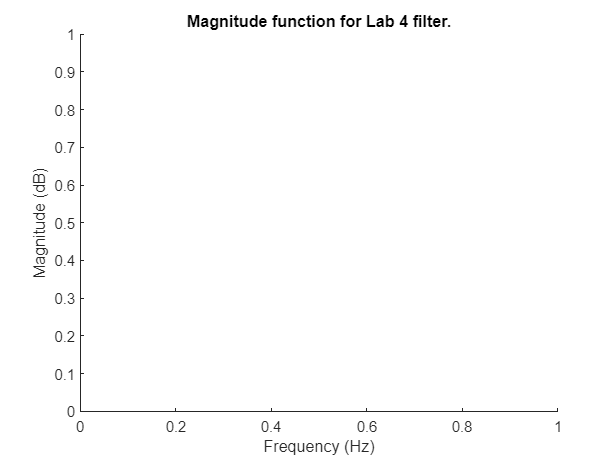


figure ;
xlabel('Frequency (Hz)') ;
ylabel('Magnitude (dB)') ; 
title('Magnitude function for Lab 4 filter.') ;


Rpp = 0.8;
Wpp =  500;
Wss = 990;

semilogx([1e3, (Wp + Wpp), (Wp + Wpp)], [-(Rp - Rpp), -(Rp - Rpp), -40], 'r:', ...
    'LineWidth', 2) ; 

Unrecognized function or variable 'Wp'.

hold on ;
semilogx([1e3, Wp, Wp], [-Rp, -Rp, -40], 'k:', 'LineWidth', 2) ; 
semilogx([1e3, (Ws - Wss), (Ws - Wss), 2e4], [0, 0, -Rs, -Rs], 'r:', ...
    'LineWidth', 2) ; 
semilogx([1e3, Ws, Ws, 2e4], [0, 0, -Rs, -Rs], 'k:', 'LineWidth', 2) ; 
xlabel('Frequency (Hz)') ;
ylabel('Magnitude (dB)') ; 
axis([1e3, 2e4, -40, 5]) ;

order = cheb1ord(Wp + Wpp, Ws - Wss, Rp - Rpp, Rs, 's') ;
[b, a] = cheby1(order, Rp - Rpp, Wp + Wpp, 's') ;
val =  polyval(b, 1i * f) ./ polyval(a, 1i * f) ;

title(['Magnitude function for Lab 4 filter. Order: ', num2str(order)]) ;

semilogx(f, 10 * log10(abs(val).^2), 'b', ...
    'LineWidth', 2) ;

% title(['Magnitude function for Lab 4 filter.  Order: ' num2str(order)]) ;




